PART B

Solution - 3

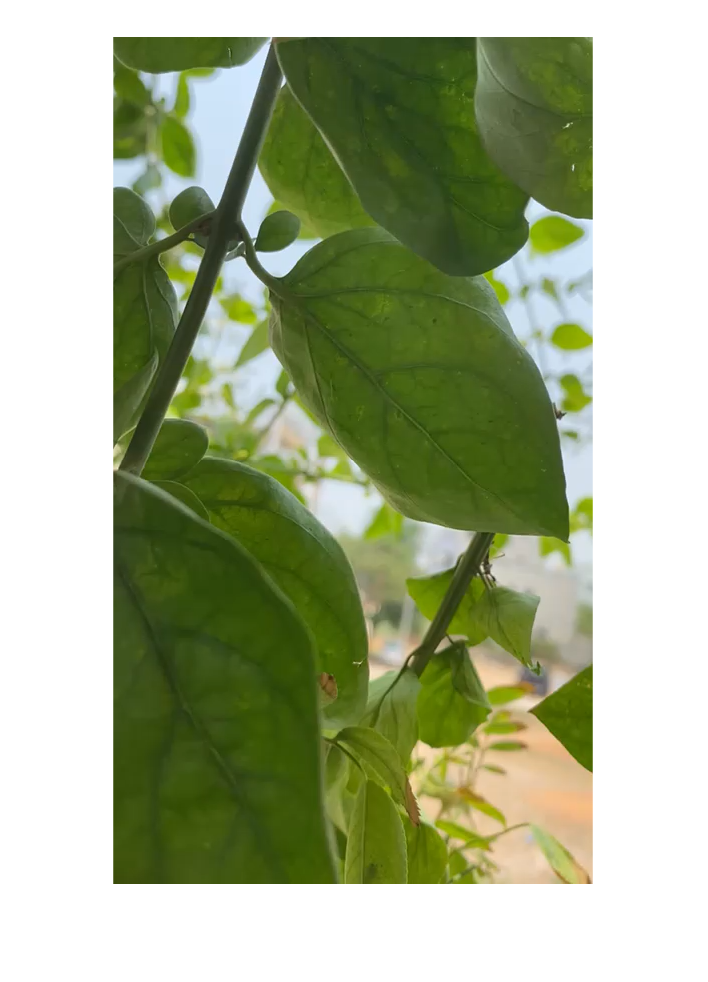

obj = VideoReader('C:\Users\shreejaa talla\Documents\CV\Assignment 2\xyz.mp4');
vid = read(obj); 
image = vid(:, :, :, 1);
imshow(image)

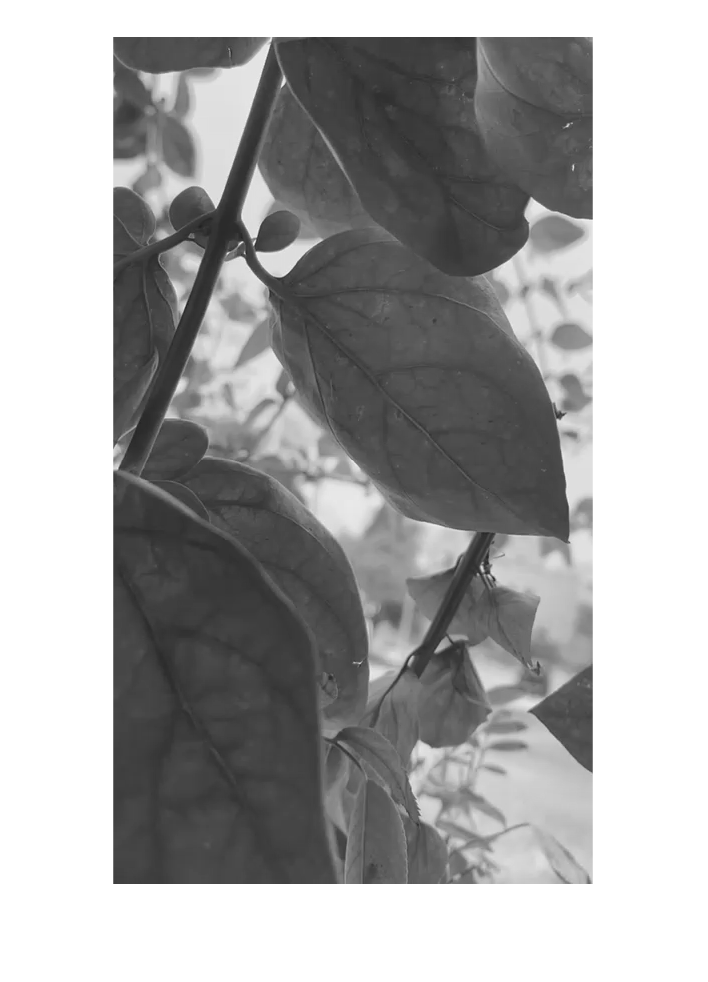

image = rgb2gray(image);
imshow(image)

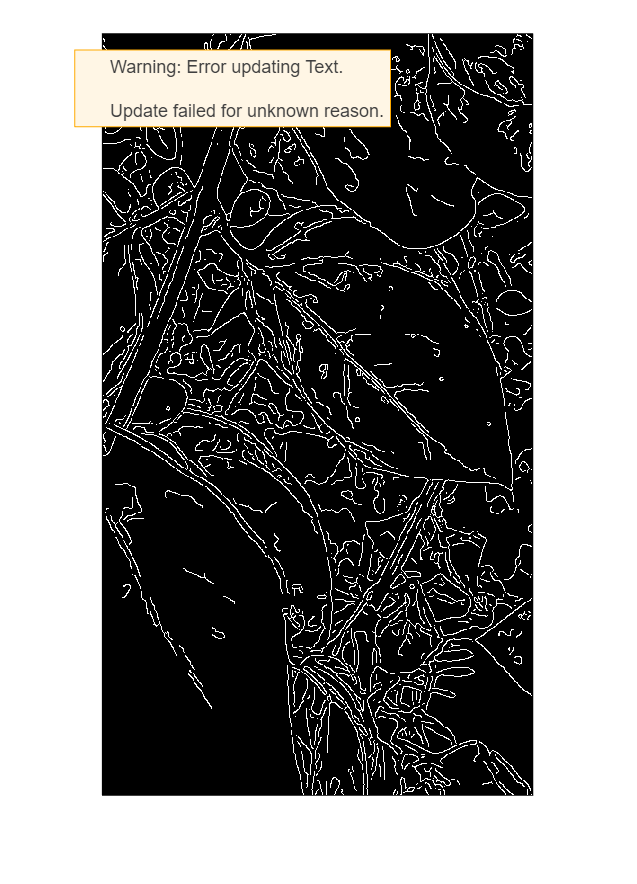

%image5 = image(25:29,6:10)
%imshow(image5)
canny_image = edge(image, 'canny');
imshow(canny_image)

Solution - 4

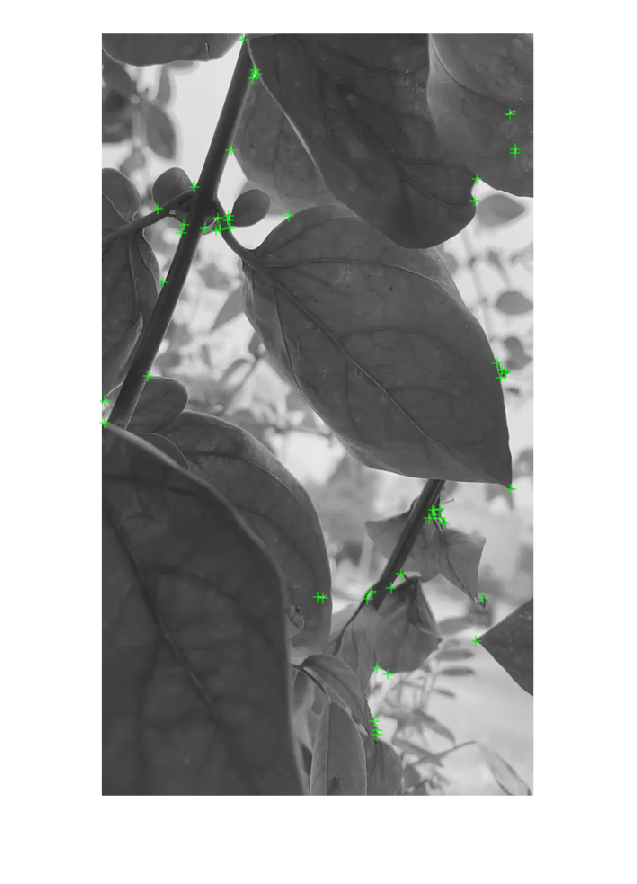

corners = detectHarrisFeatures(image);
imshow(image); hold on;
plot(corners.selectStrongest(50));